# Envelope Rhythm Metrics

## Calculating the metrics

If you just want to calculate envelope-based metrics, do the following:

%load audio files
files = ["example.wav","example2.wav"];
[X,Fs] = arrayfun(@(c)audioread(c),files,'uniformoutput',false);

%initialize an envelopeMetrics object:
em = envelopeMetrics(X,Fs{1});

%get metrics:
metrics = em.getMetrics();

disp(metrics)

    sbpr_1    scntr_1    imf_ratio21    imf_ratio32    mu_w1     mu_w2      mu_w3     pow_imf1    pow_imf2    pow_imf3    sd_w1      sd_w2      sd_w3     sumpow_imf1    sumpow_imf2    sumpow_imf3    var_w1     var_w2      var_w3 
    ______    _______    ___________    ___________    ______    ______    _______    ________    ________    ________    ______    _______    _______    ___________    ___________    

Note that the sampling rates must be identical for all of your audio files.

## The vocalic energy amplitude envelope

Envelope-based rhythm analyses are usually applied to short chunks of speech (2-3 s) with no silent pauses. The envelope is technically a "vocalic energy amplitude envelope", obtained from a low-pass zero-phase filtering of the absolute value of the band-pass filtered waveform. The vocalic energy band is defined in the `bandpass `parameter of the object. For this reason, the envelope fits the magnitude of the vocalic energy waveform better than it fits the original signal.

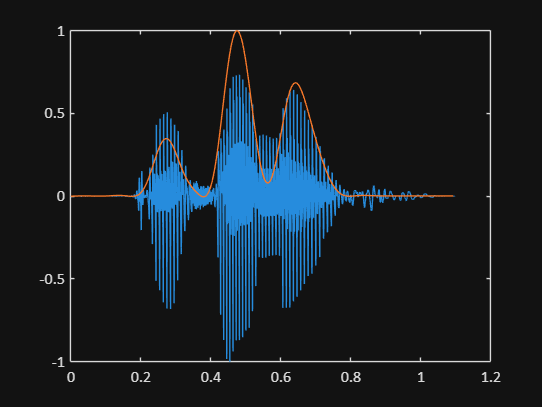

x = X{1}/max(abs(X{1})); Fs = Fs{1};
t = (0:length(x)-1)/Fs;

figls; plot(t,x); hold on;

[env,t_env] = em.extractEnvelopes();

plot(t_env{1},env{1}); 

The following object properties can be adjusted to change parameters of the envelope extraction:

- env_Passband = [400 4000] Hz

- env_Lowpass = 10 Hz

- env_BandpassFilterOrder = 4

- env_LowpassFilterOrder = 4

- env_Downsample = 100

Note that the sampling rate of the envelope is determined as:

 `[waveform sampling rate] `$\div$` [env_Downsample]`

## Envelope spectrum metrics

The envelope is zero-centered and rescaled prior to spectral analysis. The recentered envelope will generally be non-zero at its edges, so a fixed-duration edge-attenuation is applied. This duration can be adjusted with the object property `env_EdgeAttenuation`. If you would rather apply a Tukey window, set the object property `env_TukeywinParam`

The number of points for the FFT can be set in the object property `spec_Nfft` and the spectral smoothing window can be set in `spec_smoothBw`. Note that `spec_Nfft` should be larger than the number of samples in the longest envelope. All envelopes are zero-padded to `spec_Nfft`.

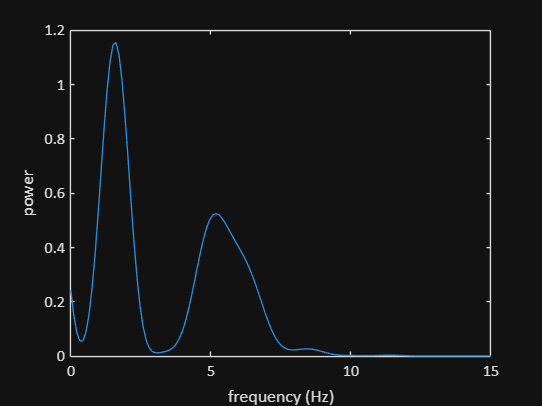

[spectra,freqs] = em.extractSpectra(env);

figls; plot(freqs,spectra{1})
xlim([0 15]); xlabel('frequency (Hz)'); ylabel('power');

Envelope power spectrum metrics can be obtained as follows:

psMetrics = em.spectralMetrics(env,freqs);
disp(psMetrics);

     sbpr_1      scntr_1
    _________    _______

    0.0057895    6.8507 
      0.48713    5.2007 



To change spectral band power ratio and spectral centroid bins, specify any number of `n x 2` arrays, where each row is a frequency range:

em.spec_PowerBins = [1 3; 3 6; 6 15];
em.spec_CentroidBins = [1 5; 1 10];

psMetrics = em.spectralMetrics(env,freqs);
disp(psMetrics);

    sbpr_1      sbpr_2     scntr_1    scntr_2
    _______    ________    _______    _______

    0.01309    0.053997    4.2269     6.8507 
    0.55758     0.55872    3.1465     5.2007 



The metric `scntr_n` is the spectral center of gravity in centroid bin `n`.

The metric `sbpr_n` is the ratio of power in power bin `n` to power in power bin `n+1.`

## Empirical mode decomposition metrics

The first IMF captures syllable-timescale oscillations in the envelope, the second IMF captures stress-timescale oscillations. Higher-order IMFs can capture lower-frequency, phrase-timescale oscillations, especially for longer chunks. Some of the EMD metrics are derived from the power of the IMFs.

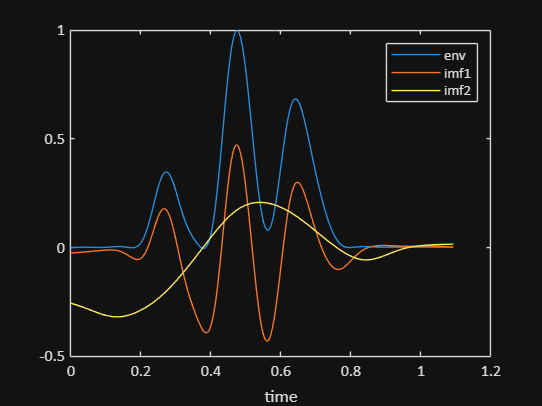

[imfs,imf_freqs] = em.getImfs(env);

figls;
plot(t_env{1},env{1}); hold on;
for i=1:2, plot(t_env{1},imfs{1}(i,:)); end
xlabel('time'); legend('env','imf1','imf2');

The number of IMFs to extract is determined by the object property `emd_MaxImf`. The empirical mode decomposition algorithm may return fewer IMFs, based on the property `emd_SiftRelTol`.

Other EMD metrics are derived from the instantaneous frequencies of the metrics. The frequencies are not meaningful where the IMF is not oscillating with substantial amplitude, so edge values and values outside of expected ranges are ignored. There are three properties that control this:

- emd_EdgeNull = 0.1 s - periods of time ignored at start/end of envelope

- emd_ImfFreqBounds = [0 13.16] Hz - absolute bounds on instantaneous freq.

- emd_FreqExclusionPercentile = 99 % - a percentile threshold across all data  

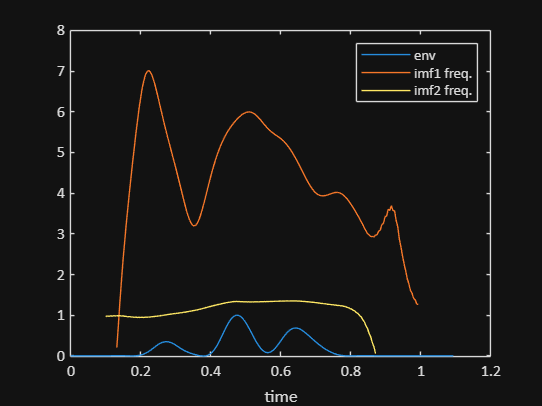

figls;
plot(t_env{1},env{1}); hold on;
for i=1:2, plot(t_env{1},imf_freqs{1}(i,:)); end
xlabel('time'); legend('env','imf1 freq.','imf2 freq.');

The following metrics are calculated:

EMD = em.emdMetrics(env);
disp(EMD);

    sumpow_imf1    pow_imf1    mu_w1     var_w1    sd_w1     sumpow_imf2    pow_imf2    mu_w2      var_w2      sd_w2     sumpow_imf3    pow_imf3     mu_w3      var_w3      sd_w3     imf_ratio21    imf_ratio32
    ___________    ________    ______    ______    ______    ___________    ________    ______    ________    _______    ___________    ________    _______    ________    _______    ___________    ___________

   

- IMF total powers: these are the powers of the IMFs, defined as $\sum_t |\mathrm{imf}(t)|$

- IMF power rate: power per second of the IMFs

- IMF average instantaneous frequency: reflects the frequency of the rhythm on the IMF timescale

- IMF standard deviation of instantaneous frequency: reflects the stability of the rhythm on the IMF timescale

- IMF variance of instantaneous frequency

- IMF power ratio: ratio of total power in adjacent pairs of IMFs. 

function [] = figls()
figure('Position',[0 0 640 480]);
end